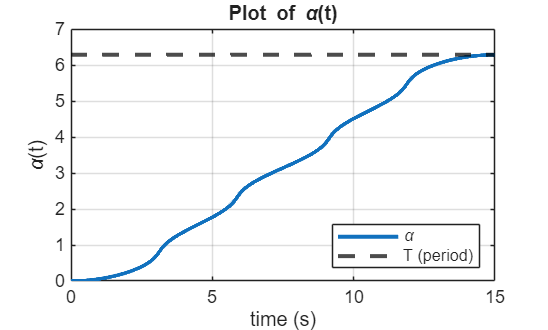

%% Step 1: Create Trapezoidal Velocity Trajectories
clear all;
close all;
clc;

%% (1a) Calculate arc length of Lissajous Curve.
% TODO: replace T, xd, yd with your our lissajous curve
T = 2*pi;
t = linspace(0,T,1000);
A = 0.15;
B = 0.15;
a = 1;
b = 2;

xd = A .* sin(a .* t);
yd = B .* sin(b .* t);

d = 0;
for i=1:length(t)-1
    d = d + sqrt( (xd(i+1)-xd(i))^2 + (yd(i+1)-yd(i))^2 );
end

% Determine the average speed, of end effector over tfinal seconds.
% TODO: replace tfinal with your code
tfinal = 15;

% calculate average speed
c = d/tfinal;

%% (1b) Use forward-euler method to numerically approximate alpha(t)
% normalized trapezoidal curve
g = @(tq, Tq, ta) (Tq/(Tq-ta))*((tq < ta) .* (tq / ta) + (tq >= ta & tq <= (Tq - ta)) .* 1 + (tq > (Tq - ta)) .* ((Tq - tq) / ta));

dt = 0.002;                     % 1/500 s
t = 0:dt:tfinal;
alpha = zeros(size(t));
ta = 0.20 * tfinal;             % 可调：10%~30%

for i=1:length(t)-1
    % xdot = ...
    % ydot = ...
    % equation (7) in the lab assignment
    % alpha(i+1) = alpha(i) + ...
    xdot = A * a * cos(a * alpha(i));
    ydot = B * b * cos(b * alpha(i));
    denom = max(sqrt(xdot^2 + ydot^2), 1e-12);
    alpha_dot = (c * g(t(i), tfinal, ta)) / denom;
    alpha(i+1) = alpha(i) + alpha_dot * dt;
end
% 终点微调到 T，避免累积误差
alpha = alpha * (T / alpha(end));

figure; plot(t,alpha,'LineWidth',2); title('Plot of \alpha(t)');
grid on; xlabel('time (s)'); ylabel('\alpha(t)');
yline(T,'k--','LineWidth',2);
legend('\alpha','T (period)','Location','southeast');

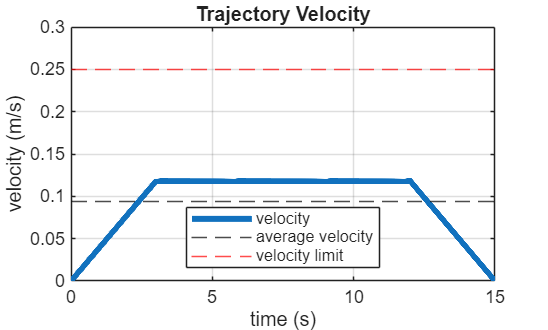


%% (1c) Combine all trajectories together.
% TODO: replace with your own lissajous curve
x = A * sin(a * alpha);
y = B * sin(b * alpha);

% Plot the speed of the trajectory as function of time.
v = sqrt( (diff(x)/dt).^2 + (diff(y)/dt).^2 );
figure;
plot(dt:dt:tfinal,v,'LineWidth',3); hold on;
yline(c,'k--');
ylim([0 0.3])
yline(0.25,'r--')
hold off;
title('Trajectory Velocity')
grid on;
xlabel('time (s)')
ylabel('velocity (m/s)')
legend('velocity', 'average velocity', 'velocity limit','Location','south')


%% Step 2: Forward Kinematics
%% (2c) Calculate T0
% these values were obtained from the URDF directly
L1 = 0.2435;
L2 = 0.2132;
W1 = 0.1311;
W2 = 0.0921;
H1 = 0.1519;
H2 = 0.0854;

% home position of end effector
M = [-1 0 0 L1+L2;
      0 0 1 W1+W2;
      0 1 0 H1-H2;
      0 0 0 1];

% screw axes (space)
S1 = [0 0 1 0 0 0]';
S2 = [0 1 0 -H1 0 0]';
S3 = [0 1 0 -H1 0 L1]';
S4 = [0 1 0 -H1 0 L1+L2]';
S5 = [0 0 -1 -W1 L1+L2 0]';
S6 = [0 1 0 H2-H1 0 L1+L2]';
S = [S1 S2 S3 S4 S5 S6];

% body screw axes
B1 = ECE569_Adjoint(M)\S1;
B2 = ECE569_Adjoint(M)\S2;
B3 = ECE569_Adjoint(M)\S3;
B4 = ECE569_Adjoint(M)\S4;
B5 = ECE569_Adjoint(M)\S5;
B6 = ECE569_Adjoint(M)\S6;
B = [B1 B2 B3 B4 B5 B6];

% joint angles
theta0 = [-1.6800; -1.4018; -1.8127; -2.9937; -0.8857; -0.0696];

% calculate the 4x4 matrix representing the transition
% from end effector frame {b} to the base frame {s} at t=0: Tsb(0)

% TODO: implement ECE569_FKinSpace and ECE569_FKinBody
T0_space = ECE569_FKinSpace(M,S,theta0)

T0_space =    -0.6987   -0.0569    0.7131    0.2154
    0.7151   -0.0248    0.6986    0.2271
   -0.0221    0.9981    0.0580    0.2966
         0         0         0    1.0000


T0_body  = ECE569_FKinBody(M,B,theta0)

T0_body =    -0.6987   -0.0569    0.7131    0.2154
    0.7151   -0.0248    0.6986    0.2271
   -0.0221    0.9981    0.0580    0.2966
         0         0         0    1.0000


T0_space-T0_body

ans = 1.0e-15 *

         0   -0.0069         0    0.0278
   -0.1110   -0.0208   -0.1110   -0.1665
   -0.0208    0.1110   -0.0208   -0.1110
         0         0         0         0


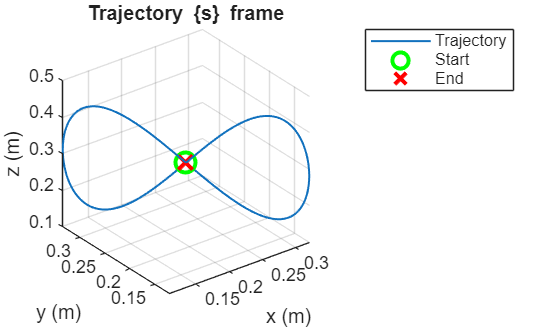

T0 = T0_body;

%% Calculate Tsd at every time step.
% Calculate Tsd(t) for t=0 to t=tfinal
% Tsd(t) = T0 * Td(t)
N = length(t);
Tsd = zeros(4,4,N);
for i=1:N
    Td = [eye(3), [x(i); y(i); 0]; 0 0 0 1];   % Rd = I3, pd = [x(t); y(t); 0]
    Tsd(:,:,i) = T0 * Td;
end

%% (2d) Plot (x,y,z) in the s frame
xs = Tsd(1,4,:);
ys = Tsd(2,4,:);
zs = Tsd(3,4,:);
figure;
plot3(xs(:), ys(:), zs(:), 'LineWidth', 1)
title('Trajectory \{s\} frame')
xlabel('x (m)')
ylabel('y (m)')
zlabel('z (m)')
hold on
plot3(xs(1),ys(1),zs(1),'go','MarkerSize',10,'LineWidth',2)
plot3(xs(end),ys(end),zs(end),'rx','MarkerSize',10,'LineWidth',2)
legend('Trajectory', 'Start', 'End')
grid on
hold off

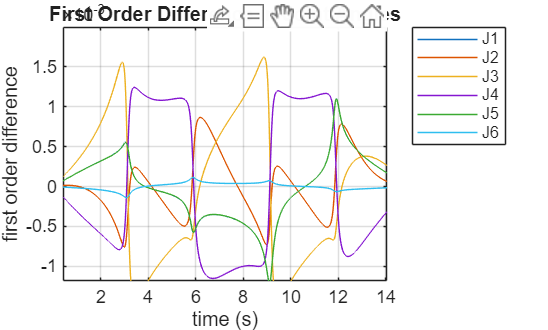


%% Step 3: Inverse Kinematics
initialguess = theta0;
Td0 = T0;   % 保留原变量名思路：仅检查 IKinBody 接口

% you need to implement IKinBody
[thetaSol, success] = ECE569_IKinBody(B,M,Td0,theta0,1e-6,1e-6);
if (~success)
    error('Error. \nCould not perform IK at index %d.',1)
end

%% (3c) Perform IK at each time step
thetaAll = zeros(6,N);
thetaAll(:,1) = theta0;

% you can comment out the waitbar functions if they aren't working
% (sometimes they don't work with .mlx files)
% If the code gets stuck here, you will need to restart MATLAB
f = waitbar(0,['Inverse Kinematics (1/',num2str(N),') complete.']);

for i=2:N
    % TODO: use previous solution as current guess
    % initialguess = ...
    initialguess = thetaAll(:, i-1);

    % TODO: calculate thetaSol for Tsd(:,:,i) with initial guess
    % [thetaSol, success] = ...
    [thetaSol, success] = ECE569_IKinBody(B, M, Tsd(:,:,i), initialguess, 1e-6, 1e-6);

    if (~success)
        close(f);
        error('Error. \nCould not perform IK at index %d.',i)
    end
    thetaAll(:,i) = thetaSol;
    waitbar(i/N,f,['Inverse Kinematics (',num2str(i),'/',num2str(N),') complete.']);
end
close(f);

%% (3c) Verify that the joint angles don't change very much
dj = diff(thetaAll');
figure;
plot(t(1:end-1), dj)
title('First Order Difference in Joint Angles')
legend('J1','J2','J3','J4','J5','J6','Location','northeastoutside')
grid on
xlabel('time (s)')
ylabel('first order difference')

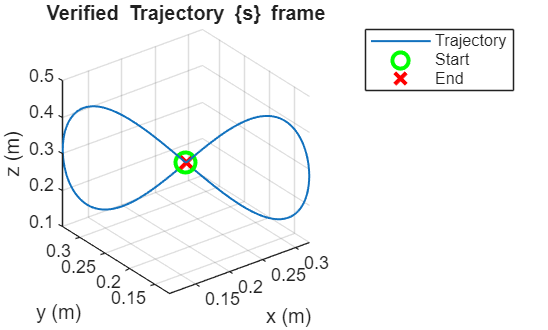


%% (3d) Verify that the joints we found actually trace out our trajectory (forward kinematics)
actualTsd = zeros(4,4,N);
for i=1:N
    % TODO: use forward kinematics to calculate Tsd from our thetaAll
    actualTsd(:,:,i) = ECE569_FKinBody(M, B, thetaAll(:, i));
end

xs = actualTsd(1,4,:);
ys = actualTsd(2,4,:);
zs = actualTsd(3,4,:);
figure;
plot3(xs(:), ys(:), zs(:), 'LineWidth', 1)
title('Verified Trajectory \{s\} frame')
xlabel('x (m)')
ylabel('y (m)')
zlabel('z (m)')
hold on
plot3(xs(1),ys(1),zs(1),'go','MarkerSize',10,'LineWidth',2)
plot3(xs(end),ys(end),zs(end),'rx','MarkerSize',10,'LineWidth',2)
legend('Trajectory', 'Start', 'End')
grid on
hold off

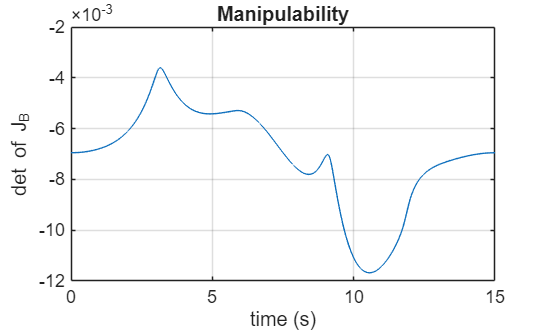


%% (3e) Verify that the end effector does not enter a kinematic singularity
body_dets = zeros(N,1);
for i=1:N
    body_dets(i) = det(ECE569_JacobianBody(B, thetaAll(:, i)));
end
figure;
plot(t, body_dets)
title('Manipulability')
grid on
xlabel('time (s)')
ylabel('det of J_B')


%% (3f) Save to CSV File
% you can play with turning the LEDs on and off
led = ones(N,1);

% save to the CSV file
data = [t' thetaAll' led];

% TODO: change the csv filename to your purdue ID
writematrix(data, 'he711.csv')
